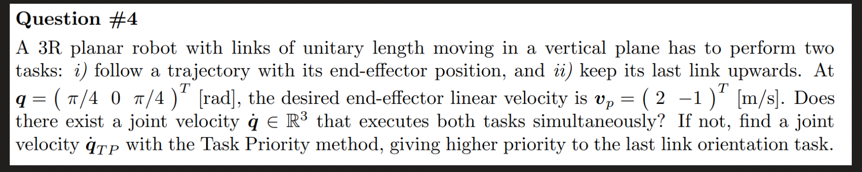

% MATLAB code to replicate the Task Priority method calculations

% Given Jacobian matrices and desired velocity vector
J1 = [1, 1, 1];
J2 = [-2.4142, -1.7071, -1; 
      1.4142, 0.7071, 0];
  
J = [J1; J2];  % Complete task Jacobian

% Desired velocity vector
v1 = 0;        % Orientation velocity
v2 = [2; -1];  % End-effector linear velocity
v = [v1; v2];

% Method 1: Pseudoinverse solution
J_pinv = pinv(J);
q_dot_PS = J_pinv * v;

% Calculate error for pseudoinverse method
e_v_PS = v - J * q_dot_PS;
norm_e_PS = norm(e_v_PS);

fprintf('Pseudoinverse solution:\n');

Pseudoinverse solution:


fprintf('q_dot_PS = [%.4f, %.4f, %.4f]^T\n', q_dot_PS(1), q_dot_PS(2), q_dot_PS(3));

q_dot_PS = [-0.8873, -0.1111, 0.6650]^T


fprintf('Error e_v_PS = [%.4f, %.4f, %.4f]^T\n', e_v_PS(1), e_v_PS(2), e_v_PS(3));

Error e_v_PS = [0.3333, 0.3333, 0.3333]^T


fprintf('Error norm ||e_v_PS|| = %.4f\n\n', norm_e_PS);

Error norm ||e_v_PS|| = 0.5774




% Method 2: Task Priority method with higher priority to orientation task
% Calculate pseudoinverse of J1
J1_pinv = J1' / (J1 * J1');  % This equals (1/3) * [1; 1; 1]

% Calculate the projection matrix P1
P1 = eye(3) - J1_pinv * J1;

% Calculate q_dot using Task Priority method
% Since v1 = 0, this simplifies to:
J2P1 = J2 * P1;
J2P1_pinv = pinv(J2P1);
q_dot_TP = J2P1_pinv * v2;

% Calculate error for task priority method
e_v_TP = v - J * q_dot_TP;
norm_e_TP = norm(e_v_TP);

fprintf('Task Priority solution:\n');

Task Priority solution:


fprintf('q_dot_TP = [%.4f, %.4f, %.4f]^T\n', q_dot_TP(1), q_dot_TP(2), q_dot_TP(3));

q_dot_TP = [-1.0607, -0.0000, 1.0607]^T


fprintf('Error e_v_TP = [%.4f, %.4f, %.4f]^T\n', e_v_TP(1), e_v_TP(2), e_v_TP(3));

Error e_v_TP = [0.0000, 0.5000, 0.5000]^T


fprintf('Error norm ||e_v_TP|| = %.4f\n', norm_e_TP);

Error norm ||e_v_TP|| = 0.7071



% Verify that the highest priority task (orientation) is satisfied
fprintf('\nVerification:\n');


Verification:


fprintf('J1 * q_dot_TP = %.4f (should be close to v1 = 0)\n', J1 * q_dot_TP);

J1 * q_dot_TP = -0.0000 (should be close to v1 = 0)
